## Zadatak 4

- Generisati po 𝑁 = 500 dvodimenzionih odbiraka iz četiri klase koje će biti linearno separabilne. Preporuka je da  to budu Gausovski raspodeljeni dvodimenzioni oblici. Izabrati jednu od metoda za klasterizaciju (c mean metod,  metod kvadratne dekompozicije) i primeniti je na formirane uzorke klasa. Izvršiti analizu osetljivosti izabranog  algoritma na početnu klasterizaciju kao i srednji broj potrebnih iteracija. Takođe izvršiti analize slučaja kada se  apriorno ne poznaje broj klasa.

- Na odbircima iz prethodne tačke izabrati jednu od metoda klasterizacije (metod maksimalne verodostojnosti ili  metod grana i granica) i primeniti je na formirane uzorke klasa. Izvršiti analizu osetljivosti izabranog algoritma na  početnu klasterizaciju kao i srednji broj potrebnih iteracija. Takođe izvršiti analize slučaja kada se apriorno ne  poznaje broj klasa.

-  Generisati po 𝑁 = 500 dvodimenzionih odbiraka iz dve klase koje su nelinearno separabilne. Izabrati jednu od  metoda za klasterizaciju koje su primenjive za nelinearno separabilne klase (metod kvadratne dekompozicije ili  metod maksimalne verodostojnosti) i ponoviti analizu iz prethodnih tačaka.

## Podaci 1

### C- mean

C-mean algoritam kao kriterijumsku funkciju koristi srednje kvadratno odstupanje odbiraka od srednje vrednosti klastera. Ideja je da svaki odbirak dodelimo klasteru cijoj je srednjoj vrednosti najblizi. Nakon svake iteracije azurira se srednja vrednost klastera i postupak se nastavlja sve dok ne dodjemo do iteracije u kojoj se nije desila ni jedna promena ili dok ne dodjemo do maksimalnog broja iteracija koje zadaje korisnik.

- Broj klastera mora unapred biti poznat. Ako nije, jedini nacin da odsredimo broj klastera je da uradimo elbow metod i odokativno ga procenimo ili se posavetujemo sa nekim ekspertom.

- Pocetna klazterizacija moze da se izvrsi cisto stohasticki i nije nam potrebno aprirorno znanje za tacnu klasterizaciju

- Klasifikacione linije su zapravo simetrale duzi koje spajaju srednje vrednosti klastera

- Ne garantuje globalnu stabilnost, cesto moze da se zaglavi u nekom lokalnom minimumu i moze da izdivergira.

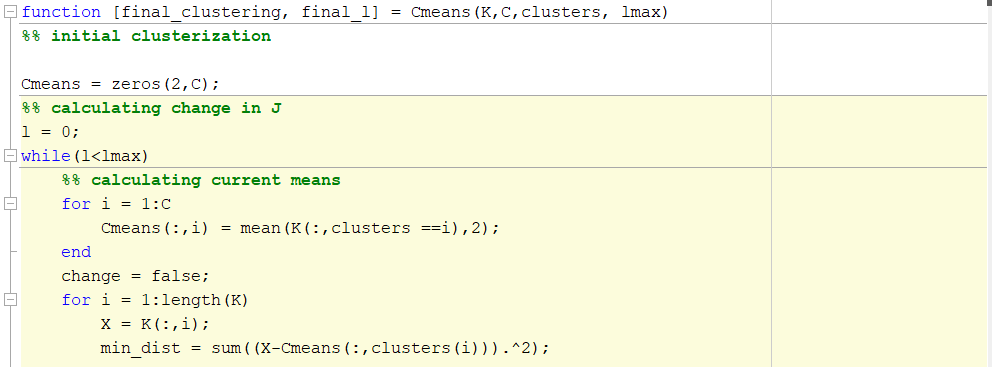

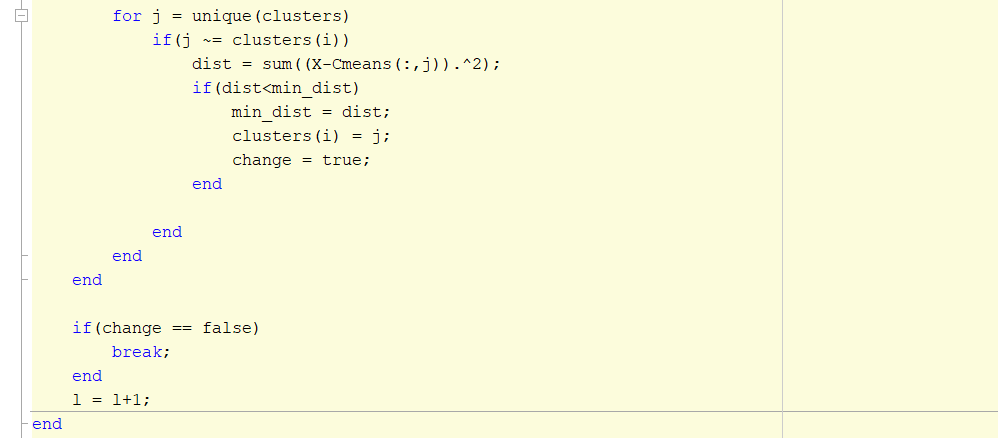

#### Generisanje podataka

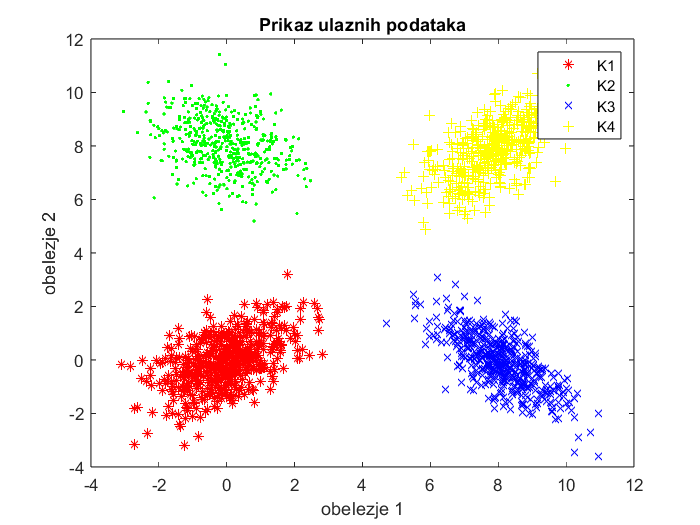

N = 500;

M1 = [0 0]';
S1 = [1 0.5; 0.5 1];
M2 = [0 8]';
S2 = [1 -0.2; -0.2 1];
M3 = [8 0]';
S3 = [1 -0.7; -0.7 1];
M4 = [8 8]';
S4 = [1 0.6; 0.6 1];

K1 = mvnrnd(M1,S1, N);
K2 = mvnrnd(M2,S2, N);
K3 = mvnrnd(M3,S3, N);
K4 = mvnrnd(M4,S4, N);
figure()
plot(K1(:,1),K1(:,2),'r*')
hold on;
plot(K2(:,1),K2(:,2),'g.')
hold on;
plot(K3(:,1),K3(:,2),'bx')
hold on;
plot(K4(:,1), K4(:,2),'y+')
hold on;
title('Prikaz ulaznih podataka')
xlabel('obelezje 1')
ylabel('obelezje 2')
legend('K1', 'K2','K3','K4')

#### Broj klasa 4, random inicijalizacija, rezultat klasterizacije

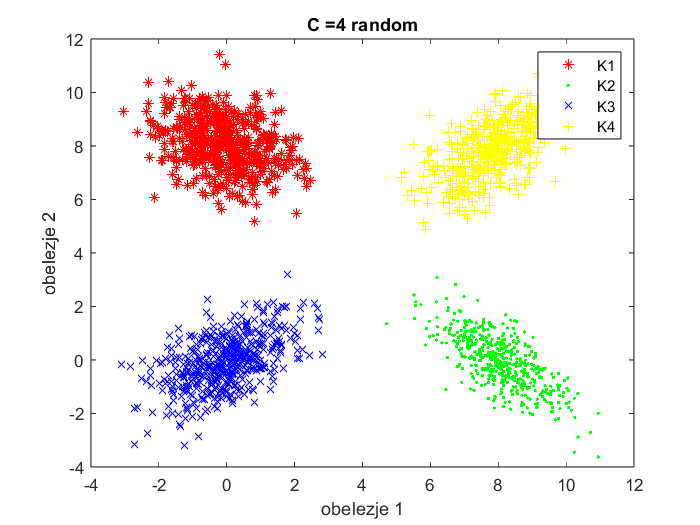

C = 4;
max_iter = 100;
K = [K1' K2' K3' K4'];
K = K(:, randperm(size(K, 2)));
initial_clusters = randi(C,1,length(K));
[clusters, iter] = Cmeans(K, C,initial_clusters,max_iter);
figure()
plot(K(1,clusters == 1),K(2,clusters == 1),'r*')
hold on;
plot(K(1,clusters == 2),K(2,clusters == 2),'g.')
hold on;
plot(K(1,clusters == 3),K(2,clusters == 3),'bx')
hold on;
plot(K(1,clusters == 4),K(2,clusters == 4),'y+')
hold on;
title('C =4 random')
xlabel('obelezje 1')
ylabel('obelezje 2')
legend('K1', 'K2','K3','K4')

#### Broj klasa 4, random inicijalizacija, srednji broj iteracija

iter_mean = 0;
for i = 1:20
    [nebitno, curr_iter]=Cmeans(K,C,initial_clusters, max_iter);
    iter_mean = iter_mean+curr_iter;
end
iter_mean_4_r = iter_mean/20;
disp(iter_mean_4_r)

     4



#### Broj klasa 4, inicijalizacija sa 100 dobrih odbiraka, rezultat klasterizacije

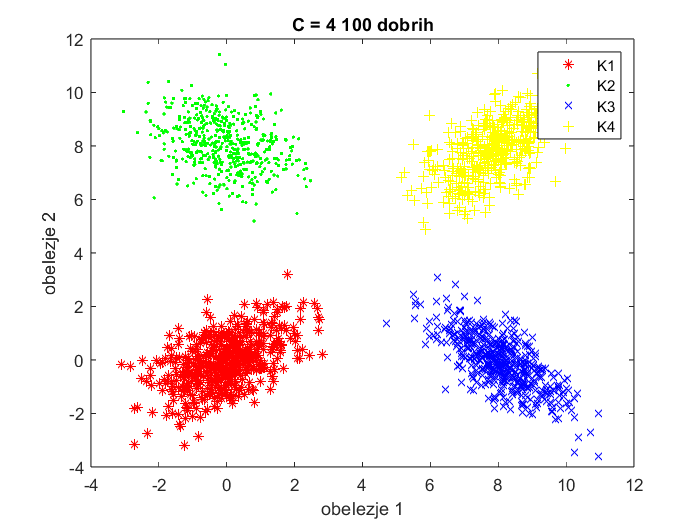

K_true = [K1(1:100,:)' K2(1:100,:)' K3(1:100,:)' K4(1:100,:)'];
clusters_true = [ones(1,100),2*ones(1,100),3*ones(1,100),4*ones(1,100)];
K_rand = [K1(101:end,:)' K2(101:end,:)' K3(101:end,:)' K4(101:end,:)'];
K_rand = K_rand(:, randperm(size(K_rand, 2)));
clusters_rand = randi(C,1,length(K_rand));

K = [K_true, K_rand];
initial_clusters = [clusters_true, clusters_rand];

[clusters, iter] = Cmeans(K, C,initial_clusters,max_iter);
figure()
plot(K(1,clusters == 1),K(2,clusters == 1),'r*')
hold on;
plot(K(1,clusters == 2),K(2,clusters == 2),'g.')
hold on;
plot(K(1,clusters == 3),K(2,clusters == 3),'bx')
hold on;
plot(K(1,clusters == 4),K(2,clusters == 4),'y+')
hold on;
title('C = 4 100 dobrih')
xlabel('obelezje 1')
ylabel('obelezje 2')
legend('K1', 'K2','K3','K4')

#### Broj klasa 4, inicijalizacija sa 100 dobrih odbiraka, srednji broj iteracija


iter_mean = 0;
for i = 1:20
    [nebitno, curr_iter]=Cmeans(K,C,initial_clusters, max_iter);
    iter_mean = iter_mean+curr_iter;
end
iter_mean_4_100_d = iter_mean/20;
disp(iter_mean_4_100_d)

     1



#### Broj klasa 4, inicijalizacija sa 100 losih odbiraka, rezultat klasterizacije

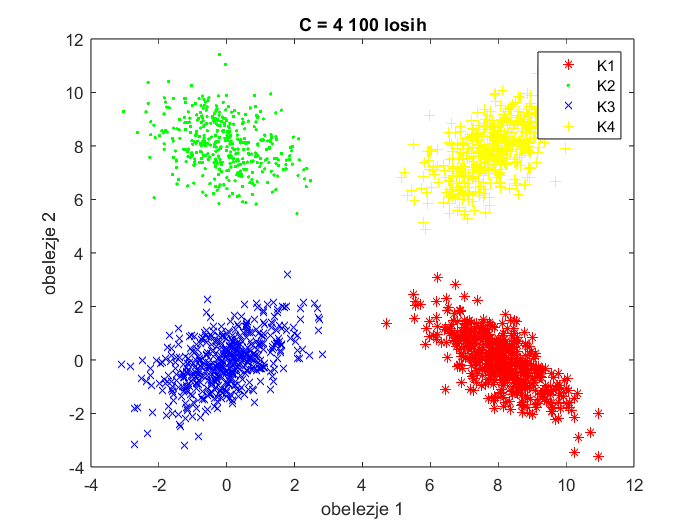

K_true = [K3(1:100,:)' K4(1:100,:)' K1(1:100,:)' K4(1:100,:)'];
clusters_true = [ones(1,100),2*ones(1,100),3*ones(1,100),4*ones(1,100)];
K_rand = [K1(101:end,:)' K2(101:end,:)' K3(101:end,:)' K4(101:end,:)'];
K_rand = K_rand(:, randperm(size(K_rand, 2)));
clusters_rand = randi(C,1,length(K_rand));

K = [K_true, K_rand];
initial_clusters = [clusters_true, clusters_rand];

[clusters, iter] = Cmeans(K, C,initial_clusters,max_iter);
figure()
plot(K(1,clusters == 1),K(2,clusters == 1),'r*')
hold on;
plot(K(1,clusters == 2),K(2,clusters == 2),'g.')
hold on;
plot(K(1,clusters == 3),K(2,clusters == 3),'bx')
hold on;
plot(K(1,clusters == 4),K(2,clusters == 4),'y+')
hold on;
title('C = 4 100 losih')
xlabel('obelezje 1')
ylabel('obelezje 2')
legend('K1', 'K2','K3','K4')

#### Broj klasa 4, inicijalizacija sa 100 losih odbiraka, srednji broj iteracija

iter_mean = 0;
for i = 1:20
    [nebitno, curr_iter]=Cmeans(K,C,initial_clusters, max_iter);
    iter_mean = iter_mean+curr_iter;
end
iter_mean_4_100_l = iter_mean/20;
disp(iter_mean_4_100_l)

     2



#### Broj klasa 5, random inicijalizacija, rezultat klasterizacije

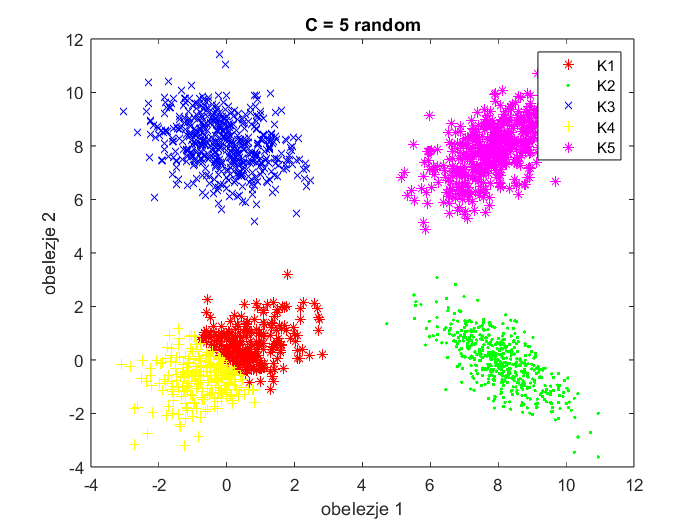

C = 5;
max_iter = 100;
K = [K1' K2' K3' K4'];
K = K(:, randperm(size(K, 2)));
initial_clusters = randi(C,1,length(K));
[clusters, iter] = Cmeans(K, C,initial_clusters,max_iter);
figure()
plot(K(1,clusters == 1),K(2,clusters == 1),'r*')
hold on;
plot(K(1,clusters == 2),K(2,clusters == 2),'g.')
hold on;
plot(K(1,clusters == 3),K(2,clusters == 3),'bx')
hold on;
plot(K(1,clusters == 4),K(2,clusters == 4),'y+')
hold on;
plot(K(1,clusters == 5),K(2,clusters == 5),'m*')
hold on;
title('C = 5 random')
xlabel('obelezje 1')
ylabel('obelezje 2')
legend('K1', 'K2','K3','K4','K5')

#### Broj klasa 5, random inicijalizacija, srednji broj iteracija

iter_mean = 0;
for i = 1:20
    [nebitno, curr_iter]=Cmeans(K,C,initial_clusters, max_iter);
    iter_mean = iter_mean+curr_iter;
end
iter_mean_5_r = iter_mean/20;
disp(iter_mean_5_r)

     8



Vidimo da posto je nasem klasifikatoru zadat veci broj klastera od onog koji realno postoji, jedna grupa klastera ce biti prazna ili ce nasilno podeli jednu grupu klastera na dve pravom na sredini klastera.

#### Broj klasa 3, random inicijalizacija, rezultat klasterizacije

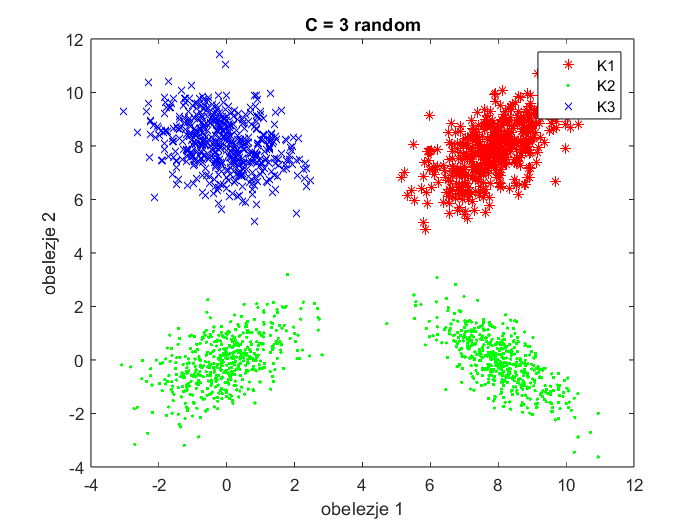

C = 3;
max_iter = 100;
K = [K1' K2' K3' K4'];
K = K(:, randperm(size(K, 2)));
initial_clusters = randi(C,1,length(K));
[clusters, iter] = Cmeans(K, C,initial_clusters,max_iter);
figure()
plot(K(1,clusters == 1),K(2,clusters == 1),'r*')
hold on;
plot(K(1,clusters == 2),K(2,clusters == 2),'g.')
hold on;
plot(K(1,clusters == 3),K(2,clusters == 3),'bx')
hold on;
title('C = 3 random')
xlabel('obelezje 1')
ylabel('obelezje 2')
legend('K1', 'K2','K3')

Vidimo da s obzirom da u realnosti imamo vise klastera nego sto smo zadali klasifikatoru da nadje on ce spojiti dve grupe u jednu.

#### Broj klasa 3, random inicijalizacija, srednji broj iteracija

iter_mean = 0;
for i = 1:20
    [nebitno, curr_iter]=Cmeans(K,C,initial_clusters, max_iter);
    iter_mean = iter_mean+curr_iter;
end
iter_mean_3_r = iter_mean/20;
disp(iter_mean_3_r)

     2



A = [iter_mean_3_r,iter_mean_4_r, iter_mean_5_r];
T = array2table(A);
T.Properties.VariableNames(1:3) = {'C=3','C=4','C=5'};
T.Properties.RowNames(1) = {'Zavisnost od broja klasa'};
disp(T)

                                C=3    C=4    C=5
                                ___    ___    ___

    Zavisnost od broja klasa     2      4      8 



A = [iter_mean_4_100_d,iter_mean_4_r, iter_mean_4_100_l];
T = array2table(A);
T.Properties.VariableNames(1:3) = {'100 dobrih','random','100 losih'};
T.Properties.RowNames(1) = {'Zavisnost od inicijalizacije'};
disp(T)

                                    100 dobrih    random    100 losih
                                    __________    ______    _________

    Zavisnost od inicijalizacije        1           4           2    



Mozemo primetiti da zadati broj klasa ne utice na srednji broj iteracija ali incijalizacija itekako utice. Ovo ima smisla jer je nasem klasifikatoru mnogo lakse da klasterizuje podatke ako mu na samom pocetku zadamo 100 dobrih pa mu treba manji broj iteracija, a ako mu zadamo broj losih bice mu mnogo teze da dodje do dobre klasterizacije pa ce mu samim tim biti potreban veci broj iteracija.

### MLE klasterizacija

Ovaj metod pretpostavlja da su fgv oblika  Gausovski raspodeljene pa je samim tim zajednicka fgv svih oblika mesavina gausovskih raspodela. Kriterijumska funkcija je suma zajednickih fgv pri uslovu da je zbir apriornih verovatnca jednak 1.

Izjednacavanjem izvoda po apriornoj verovatnoci, ocekivanju i kovarijacionoj matrici sa nulom dobijaju se formule koriscene u iterativnoj proceduri.

Prvi korak je racunanje ovih parametara a sledeci racunanje aposteriornih verovatnoca na osnovu njih.

Svaki odbirak se dodeljuje onom klasteru cija aposteriorna verovatnoca ima vecu vrednost u njemu.

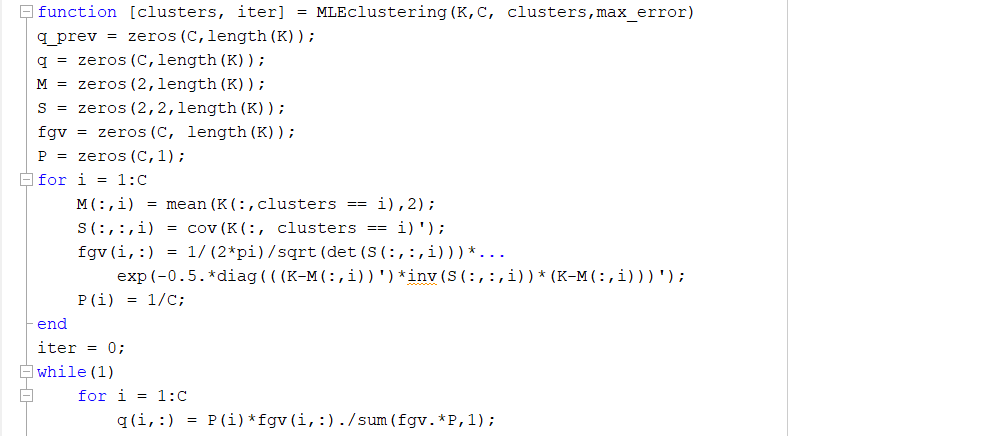

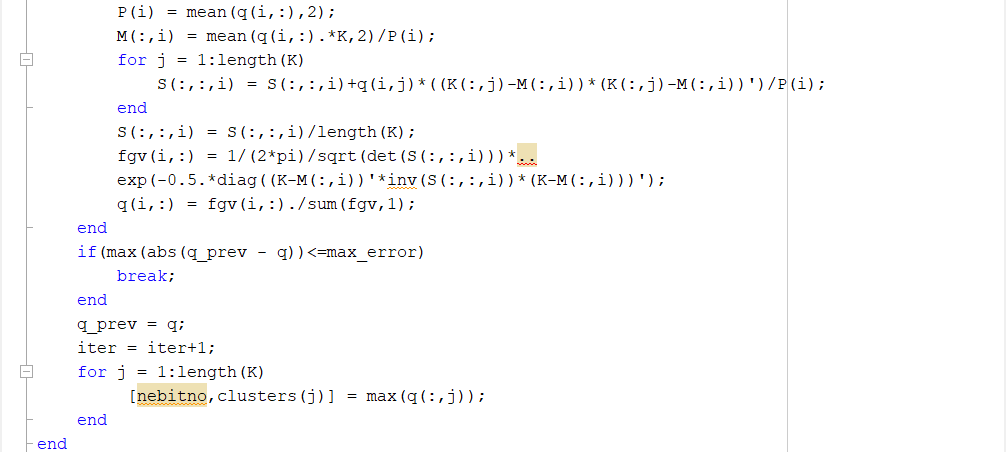

#### Broj klasa 5, random inicijalizacija, rezultat klasterizacije

C = 5;
K_true = [K1(1:100,:)' K2(1:100,:)' K3(1:100,:)' K4(1:100,:)'];
clusters_true = [ones(1,100),2*ones(1,100),3*ones(1,100),4*ones(1,100)];
K_rand = [K1(101:end,:)' K2(101:end,:)' K3(101:end,:)' K4(101:end,:)'];
K_rand = K_rand(:, randperm(size(K_rand, 2)));
clusters_rand = randi(C,1,length(K_rand));

K = [K_true, K_rand];
initial_clusters = [clusters_true, clusters_rand];

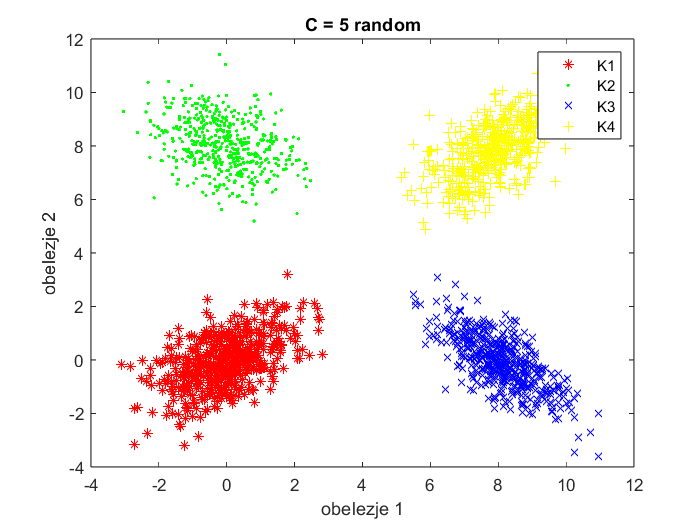

max_error = 1e-2;
[clusters,iter] = MLEclustering(K,C,initial_clusters, 1e-2);
figure()
plot(K(1,clusters == 1),K(2,clusters == 1),'r*')
hold on;
plot(K(1,clusters == 2),K(2,clusters == 2),'g.')
hold on;
plot(K(1,clusters == 3),K(2,clusters == 3),'bx')
hold on;
plot(K(1,clusters == 4),K(2,clusters == 4),'y+')
hold on;
title('C = 5 random')
xlabel('obelezje 1')
ylabel('obelezje 2')
legend('K1', 'K2','K3','K4')

#### Broj klasa 5, random inicijalizacija, srednji broj iteracija


iter_mean = 0;
for i = 1:20
    [nebitno, curr_iter]=MLEclustering(K,C,initial_clusters, max_error);
    iter_mean = iter_mean+curr_iter;
end
iter_mean_5_r = iter_mean/20;
disp(iter_mean_5_r)

    32



#### Broj klasa 4, random inicijalizacija, rezultat klasterizacije

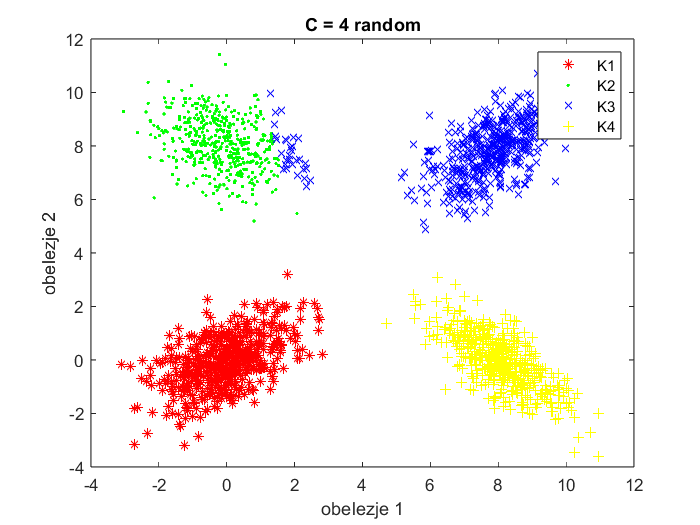

C = 4;
max_iter = 100;
K = [K1' K2' K3' K4'];
K = K(:, randperm(size(K, 2)));
initial_clusters = randi(C,1,length(K));
[clusters, iter] = MLEclustering(K,C,initial_clusters, 1e-2);
figure()
plot(K(1,clusters == 1),K(2,clusters == 1),'r*')
hold on;
plot(K(1,clusters == 2),K(2,clusters == 2),'g.')
hold on;
plot(K(1,clusters == 3),K(2,clusters == 3),'bx')
hold on;
plot(K(1,clusters == 4),K(2,clusters == 4),'y+')
hold on;
title('C = 4 random')
xlabel('obelezje 1')
ylabel('obelezje 2')
legend('K1', 'K2','K3','K4')

#### Broj klasa 4, random inicijalizacija, srednji broj iteracija

iter_mean = 0;
for i = 1:20
    [nebitno, curr_iter]=MLEclustering(K,C,initial_clusters, 1e-2);
    iter_mean = iter_mean+curr_iter;
end
iter_mean_4_r = iter_mean/20;
disp(iter_mean_4_r)

     1



#### Broj klasa 3, random inicijalizacija, rezultat klasterizacije

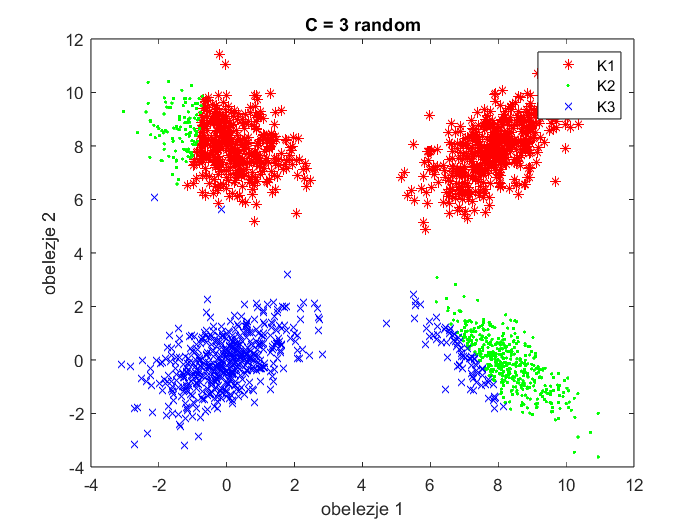

C = 3;
K_true = [K1(1:100,:)' K2(1:100,:)' K3(1:100,:)' K4(1:100,:)'];
clusters_true = [ones(1,100),2*ones(1,100),3*ones(1,100),4*ones(1,100)];
K_rand = [K1(101:end,:)' K2(101:end,:)' K3(101:end,:)' K4(101:end,:)'];
K_rand = K_rand(:, randperm(size(K_rand, 2)));
clusters_rand = randi(C,1,length(K_rand));
%%
max_iter = 100;
K = [K1' K2' K3' K4'];
K = K(:, randperm(size(K, 2)));
initial_clusters = randi(C,1,length(K));
[clusters, iter] = MLEclustering(K,C,initial_clusters, 1e-2);
figure()
plot(K(1,clusters == 1),K(2,clusters == 1),'r*')
hold on;
plot(K(1,clusters == 2),K(2,clusters == 2),'g.')
hold on;
plot(K(1,clusters == 3),K(2,clusters == 3),'bx')
hold on;
title('C = 3 random')
xlabel('obelezje 1')
ylabel('obelezje 2')
legend('K1', 'K2','K3')

#### Broj klasa 3, random inicijalizacija, srednji broj iteracija

iter_mean = 0;
for i = 1:20
    [nebitno, curr_iter]=MLEclustering(K,C,initial_clusters, 1e-2);
    iter_mean = iter_mean+curr_iter;
end
iter_mean_3_r = iter_mean/20;
disp(iter_mean_3_r)

     2



#### Broj klasa 4, inicijalizacija sa 100 dobrih odbiraka, rezultat klasterizacije

C = 4

C = 4

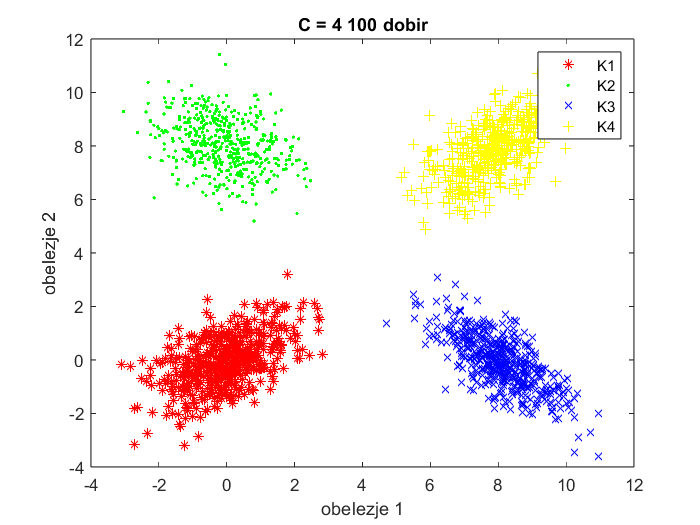

K_true = [K1(1:100,:)' K2(1:100,:)' K3(1:100,:)' K4(1:100,:)'];
clusters_true = [ones(1,100),2*ones(1,100),3*ones(1,100),4*ones(1,100)];
K_rand = [K1(101:end,:)' K2(101:end,:)' K3(101:end,:)' K4(101:end,:)'];
K_rand = K_rand(:, randperm(size(K_rand, 2)));
clusters_rand = randi(C,1,length(K_rand));

K = [K_true, K_rand];
initial_clusters = [clusters_true, clusters_rand];

[clusters, iter] = MLEclustering(K,C,initial_clusters, 1e-2);
figure()
plot(K(1,clusters == 1),K(2,clusters == 1),'r*')
hold on;
plot(K(1,clusters == 2),K(2,clusters == 2),'g.')
hold on;
plot(K(1,clusters == 3),K(2,clusters == 3),'bx')
hold on;
plot(K(1,clusters == 4),K(2,clusters == 4),'y+')
hold on;
title('C = 4 100 dobir')
xlabel('obelezje 1')
ylabel('obelezje 2')
legend('K1', 'K2','K3','K4')

#### Broj klasa 4, inicijalizacija sa 100 dobrih odbiraka, srednji broj iteracija


iter_mean = 0;
for i = 1:20
    [nebitno, curr_iter]=MLEclustering(K,C,initial_clusters, 1e-2);
    iter_mean = iter_mean+curr_iter;
end
iter_mean_4_100_d = iter_mean/20;
disp(iter_mean_4_100_d)

    16



#### Broj klasa 4, inicijalizacija sa 100 losih odbiraka, rezultat klasterizacije

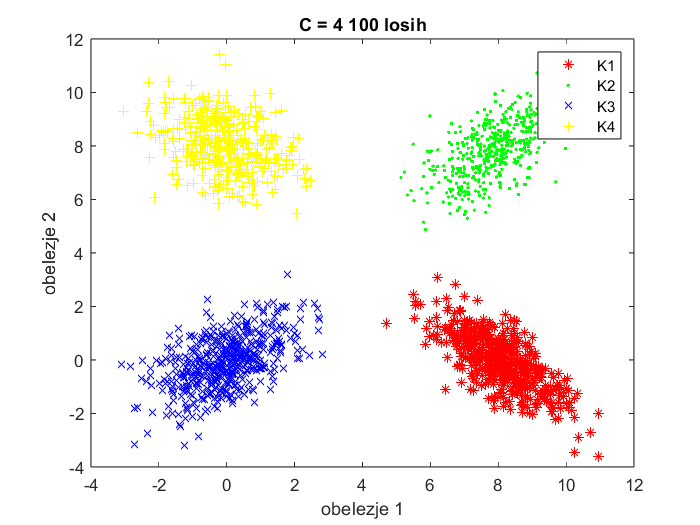

K_true = [K3(1:100,:)' K4(1:100,:)' K1(1:100,:)' K4(1:100,:)'];
clusters_true = [ones(1,100),2*ones(1,100),3*ones(1,100),4*ones(1,100)];
K_rand = [K1(101:end,:)' K2(101:end,:)' K3(101:end,:)' K4(101:end,:)'];
K_rand = K_rand(:, randperm(size(K_rand, 2)));
clusters_rand = randi(C,1,length(K_rand));

K = [K_true, K_rand];
initial_clusters = [clusters_true, clusters_rand];

[clusters, iter] = MLEclustering(K,C,initial_clusters, 1e-2);
figure()
plot(K(1,clusters == 1),K(2,clusters == 1),'r*')
hold on;
plot(K(1,clusters == 2),K(2,clusters == 2),'g.')
hold on;
plot(K(1,clusters == 3),K(2,clusters == 3),'bx')
hold on;
plot(K(1,clusters == 4),K(2,clusters == 4),'y+')
hold on;
title('C = 4 100 losih')
xlabel('obelezje 1')
ylabel('obelezje 2')
legend('K1', 'K2','K3','K4')

#### Broj klasa 4, inicijalizacija sa 100 losih odbiraka, srednji broj iteracija

iter_mean = 0;
for i = 1:20
    [nebitno, curr_iter]=MLEclustering(K,C,initial_clusters, 1e-2);
    iter_mean = iter_mean+curr_iter;
end
iter_mean_4_100_l = iter_mean/20;
disp(iter_mean_4_100_l)

    19



A = [iter_mean_3_r,iter_mean_4_r, iter_mean_5_r];
T = array2table(A);
T.Properties.VariableNames(1:3) = {'C=3','C=4','C=5'};
T.Properties.RowNames(1) = {'Zavisnost od broja klasa'};
disp(T)

                                C=3    C=4    C=5
                                ___    ___    ___

    Zavisnost od broja klasa     2      1     32 



A = [iter_mean_4_100_d,iter_mean_4_r, iter_mean_4_100_l];
T = array2table(A);
T.Properties.VariableNames(1:3) = {'100 dobrih','random','100 losih'};
T.Properties.RowNames(1) = {'Zavisnost od inicijalizacije'};
disp(T)

                                    100 dobrih    random    100 losih
                                    __________    ______    _________

    Zavisnost od inicijalizacije        16          1          19    



Prvo, primetimo da je MLE znatno osetljiviji na zadati broj klasa. Ako mu zadamo  pogresan broj klasa klasterizacija nece biti mnogo smislena(cak nece jedan klaster podeliti na dva ili spojiti dva klastera) i treba mu mnogo vise iteracija da bi je izvrsio. Takodje, najbolje rezultate dobijamo za random inicijalizaciju.

### Metod normalne dekompozicije

Metod kvadratne dekompozicije je jedan od metoda normalne dekompozicije. On je jako slican C-means metodu jedina razlika je sto kriterijumska funkcija vise nije rastojanje od srednje vrednosti vec aposteriorna verovatnoca u slucaju Gausove raspodele.

- Zahteva apriorno znanje, ako ga nemamo, rezultat klasterizacije moze biti jako los

- zahteva da znamo broj klastera

- Moguce je da klasifikaciona linija bude nelinearna kriva za razliku od C means gde je to bila prava ALI moze biti samo kriva drugog reda

- Nije zagarantovan globalni minimum

- Slozeniji je od K-mean i zahteva veci broj iteracija

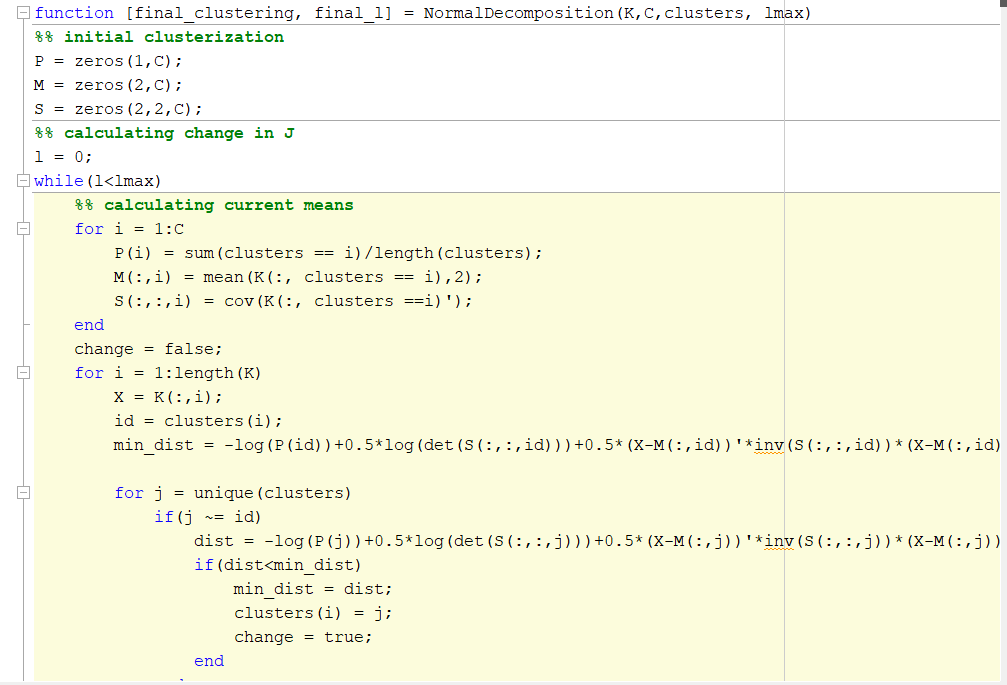

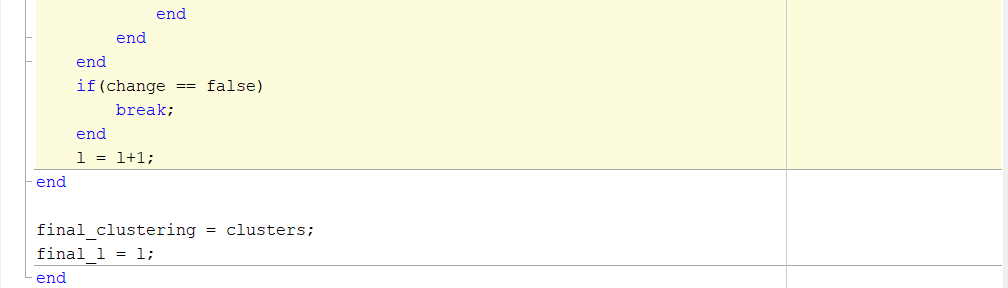

#### Generisanje nelinearno separabilnih podataka

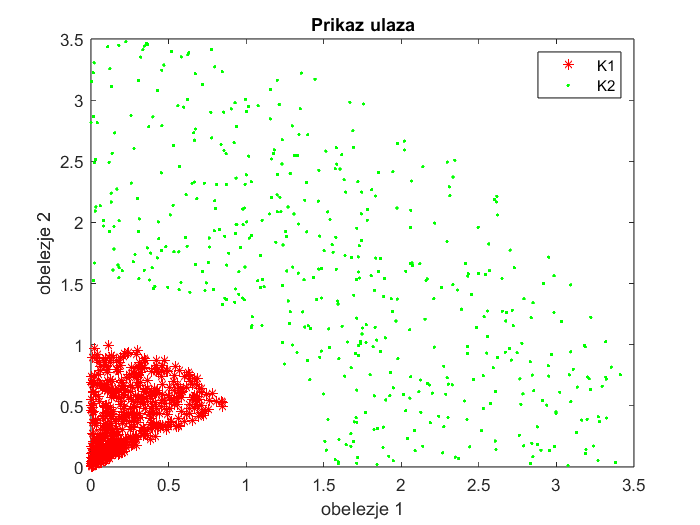

N = 500;
x = rand(1,500)*10-5;
rho = rand(1,500);
theta = rand(1,500)*pi/3;

K1 = [rho.*sin(theta);rho.*cos(theta)];

rho = rand(1,500)*2+1.5;
theta = rand(1,500)*pi/2;

K2 = [rho.*sin(theta);rho.*cos(theta)];

figure()
plot(K1(1,:),K1(2,:),'r*')
hold on;
plot(K2(1,:),K2(2,:),'g.')
hold on;
title('Prikaz ulaza')
xlabel('obelezje 1')
ylabel('obelezje 2')
legend('K1', 'K2')

#### Broj klasa 2, random inicijalizacija, rezultat klasterizacije

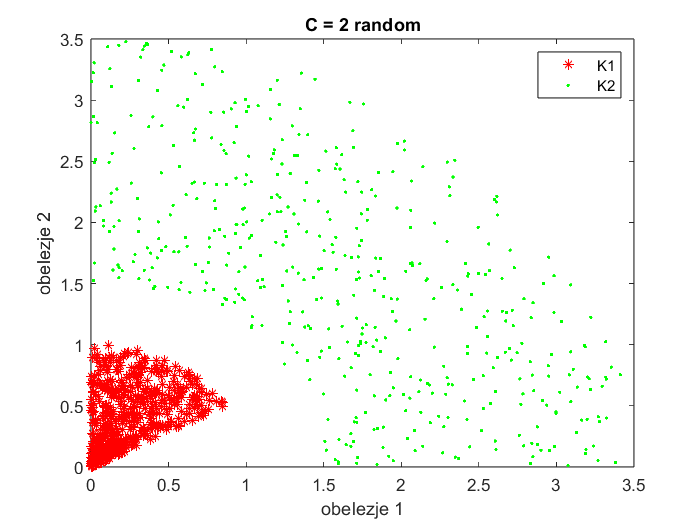

C = 2;
max_iter = 100;
K = [K1 K2];
K = K(:, randperm(size(K, 2)));

initial_clusters = randi(C,1,length(K));
[clusters, iter] = NormalDecomposition(K, C,initial_clusters,max_iter);
figure()
plot(K(1,clusters == 1),K(2,clusters == 1),'r*')
hold on;
plot(K(1,clusters == 2),K(2,clusters == 2),'g.')
title('C = 2 random')
xlabel('obelezje 1')
ylabel('obelezje 2')
legend('K1', 'K2')

#### Broj klasa 2, random inicijalizacija, srednji broj iteracija

iter_mean = 0;
for i = 1:20
    [nebitno, curr_iter]=NormalDecomposition(K,C,initial_clusters, max_iter);
    iter_mean = iter_mean+curr_iter;
end
iter_mean_2_r = iter_mean/20;
disp(iter_mean_2_r)

     7



S obzirom da ovaj metod podrazumeva normalnu raspodelu pokusace da podeli skup podataka na dva dela kao da su oni Gausovski raspodeljeni zbog cega ne uspeva dobro da klasterizuje nase podatke.

#### Broj klasa 2,inicijalizacija sa 100 dobrih, rezultat klasterizacije

K_true = [K1(:,1:100) K2(:,1:100)];
clusters_true = [ones(1,100),2*ones(1,100)];
K_rand = [K1(:,101:end) K2(:,101:end)];
K_rand = K_rand(:, randperm(size(K_rand, 2)));
clusters_rand = randi(C,1,length(K_rand));

K = [K_true, K_rand];
initial_clusters = [clusters_true, clusters_rand];

#### Broj klasa 2, inicijalizacija sa 100 dobrih, srednji broj iteracija

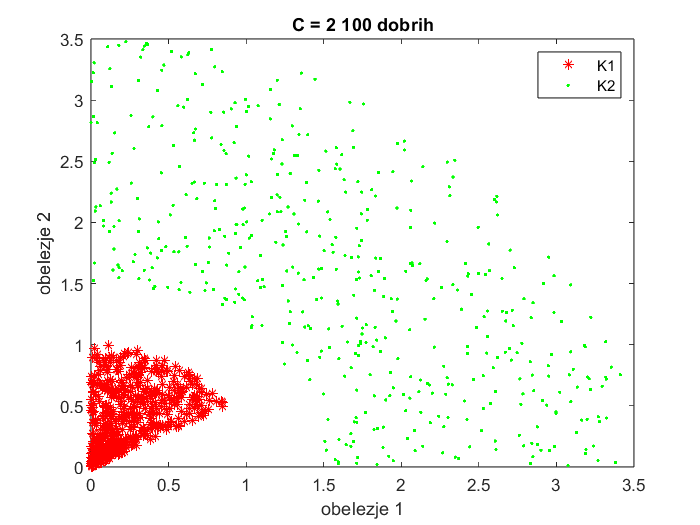


[clusters, iter] = NormalDecomposition(K, C,initial_clusters,max_iter);
figure()
plot(K(1,clusters == 1),K(2,clusters == 1),'r*')
hold on;
plot(K(1,clusters == 2),K(2,clusters == 2),'g.')
title('C = 2 100 dobrih')
xlabel('obelezje 1')
ylabel('obelezje 2')
legend('K1', 'K2')

iter_mean = 0;
for i = 1:20
    [nebitno, curr_iter]=NormalDecomposition(K,C,initial_clusters, max_iter);
    iter_mean = iter_mean+curr_iter;
end
iter_mean_2_100_d = iter_mean/20;
disp(iter_mean_2_100_d)

     3



Kada mu zadamo sto dobrih za pocetne uslove klasterizacija je dobro izvrsena, ali 100 semplova na 500 je 1/5 sto u realnosti ako nam je potrebna klasterizacija a ne klasifikacija necemo moci da imamo.

#### Broj klasa 2, inicijalizacija sa 100 losih, rezultat klasterizacije

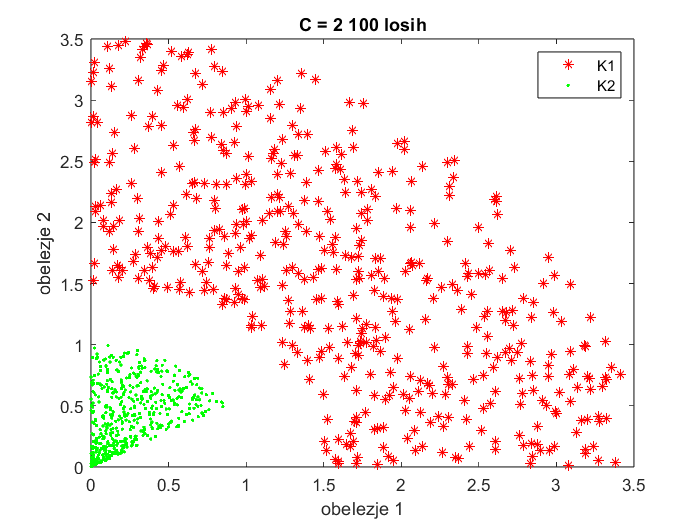

K_true = [K2(:,1:100) K1(:,1:100) ];
clusters_true = [ones(1,100),2*ones(1,100)];
K_rand = [K1(:,101:end) K2(:,101:end)];
K_rand = K_rand(:, randperm(size(K_rand, 2)));
clusters_rand = randi(C,1,length(K_rand));

K = [K_true, K_rand];
initial_clusters = [clusters_true, clusters_rand];
[clusters, iter] = NormalDecomposition(K, C,initial_clusters,max_iter);
figure()
plot(K(1,clusters == 1),K(2,clusters == 1),'r*')
hold on;
plot(K(1,clusters == 2),K(2,clusters == 2),'g.')
title('C = 2 100 losih')
xlabel('obelezje 1')
ylabel('obelezje 2')
legend('K1', 'K2')

#### Broj klasa 2, inicijalizacija sa 100 losih, srednji broj iteracija


iter_mean = 0;
for i = 1:20
    [nebitno, curr_iter]=NormalDecomposition(K,C,initial_clusters, max_iter);
    iter_mean = iter_mean+curr_iter;
end
iter_mean_2_100_l = iter_mean/20;
disp(iter_mean_2_100_l)

     2



Za slucaj dva klastera, broj losih odbiraka dace isti rezultat kao ako mu damo dobre zato sto podatke treba da podelimo samo na dva skupa

#### Broj klasa 3, random inicijalizacija, rezultat klasterizacije

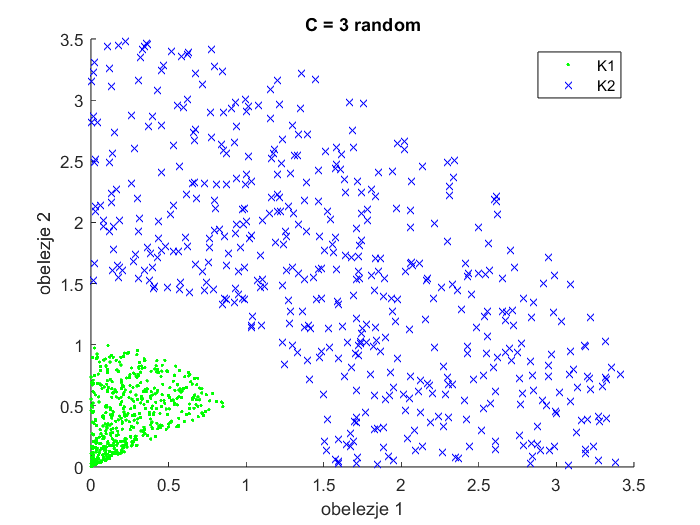

C = 3;
max_iter = 100;
K = [K1 K2];
K = K(:, randperm(size(K, 2)));
initial_clusters = randi(C,1,length(K));
[clusters, iter] = NormalDecomposition(K, C,initial_clusters,max_iter);
figure()
plot(K(1,clusters == 1),K(2,clusters == 1),'r*')
hold on;
plot(K(1,clusters == 2),K(2,clusters == 2),'g.')
hold on;
plot(K(1,clusters == 3),K(2,clusters == 3),'bx')
hold on;
title('C = 3 random')
xlabel('obelezje 1')
ylabel('obelezje 2')
legend('K1', 'K2','K3')

#### Broj klasa 3, random inicijalizacija, srednji broj iteracija

iter_mean = 0;
for i = 1:20
    [nebitno, curr_iter]=NormalDecomposition(K,C,initial_clusters, max_iter);
    iter_mean = iter_mean+curr_iter;
end
iter_mean_3_r = iter_mean/20;
disp(iter_mean_3_r)

    14



Primetimo da se sve vreme klaster podataka oko centra mnogo lakse klasterizuje jer ga mozemo obuhvatiti gausovom raspodelom dok prsten ne mozemo jer ima supljinu u centru koju Gausova raspodela mora da obezbedi. Klasterizacija na tri dela je mnogo laksa jer mozemo postaviti dva centra na prstenu pa obuhvatiti Gausovom rapsodelom svaki od njih. Ipak taj nacin klasterizacije nije intuitivan jer covek ne bi percipirao te dve vrste podataka kao da pripadaju razlicitom skupu.

#### Broj klasa 5, random inicijalizacija, rezultat klasterizacije

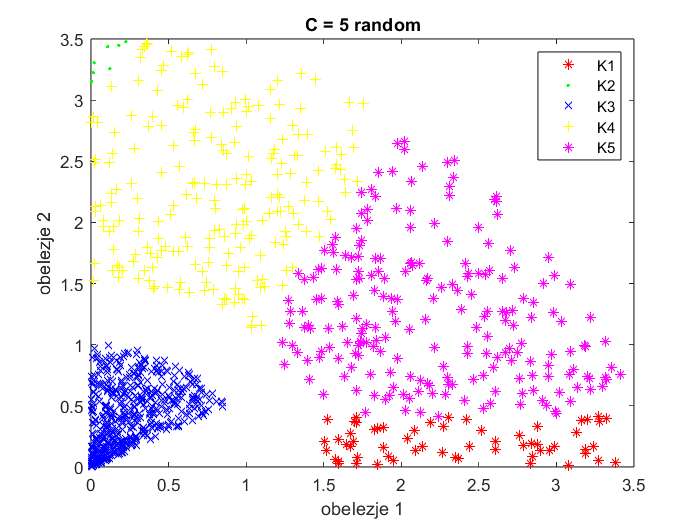

C = 5;
max_iter = 100;
K = [K1 K2];
K = K(:, randperm(size(K, 2)));
initial_clusters = randi(C,1,length(K));
[clusters, iter] = NormalDecomposition(K, C,initial_clusters,max_iter);
figure()
plot(K(1,clusters == 1),K(2,clusters == 1),'r*')
hold on;
plot(K(1,clusters == 2),K(2,clusters == 2),'g.')
hold on;
plot(K(1,clusters == 3),K(2,clusters == 3),'bx')
hold on;
plot(K(1,clusters == 4),K(2,clusters == 4),'y+')
hold on;
plot(K(1,clusters == 5),K(2,clusters == 5),'m*')
hold on;
title('C = 5 random')
xlabel('obelezje 1')
ylabel('obelezje 2')
legend('K1', 'K2','K3','K4','K5')

#### Broj klasa 5, random inicijalizacija, srednji broj iteracija

iter_mean = 0;
for i = 1:20
    [nebitno, curr_iter]=NormalDecomposition(K,C,initial_clusters, max_iter);
    iter_mean = iter_mean+curr_iter;
end
iter_mean_5_r= iter_mean/20;
disp(iter_mean_5_r)

    12



Za slucaj 5 klasa vazi isto kao za 3.

#### Sumarni prikaz srednjeg broja iteracija

A = [iter_mean_2_r,iter_mean_3_r, iter_mean_5_r];
T = array2table(A);
T.Properties.VariableNames(1:3) = {'C=2','C=3','C=5'};
T.Properties.RowNames(1) = {'Zavisnost od broja klasa'};
disp(T)

                                C=2    C=3    C=5
                                ___    ___    ___

    Zavisnost od broja klasa     7     14     12 



A = [iter_mean_2_100_d,iter_mean_2_r, iter_mean_2_100_l];
T = array2table(A);
T.Properties.VariableNames(1:3) = {'100 dobrih','random','100 losih'};
T.Properties.RowNames(1) = {'Zavisnost od inicijalizacije'};
disp(T)

                                    100 dobrih    random    100 losih
                                    __________    ______    _________

    Zavisnost od inicijalizacije        3           7           2    



Srednji broj iteracija raste sa brojem klasa, a najteza je random inicijalizacija i potreban je veci broj itercija nego kod C-means.